# Kuka LBR Group 4 Project Week 11

* Robert Garrone, Blerand Qeriqi and Tejinder Jutla*

*    Worcester Polytechnic Institute*

## Introduction:

In this week, the group was tasked to model the Kuka LBR's trajectory specifically pertaining to joint space and task space coordinates. In this assignment, we will look into the definitions of Task space and Joint space. We will visualize our robot's Task and Joint space trajectories and confirm if our results concur with the definitions and trajectories provided in our reference materials.

The following is the question that we will attempt to answer:

- Rewrite your code you created to describe your robot in Robotics Toolkit, Create or find a URDF file for your co-robot, Create waypoints and generate the trajectory in Joint Space and Task space.

- Draw the joint position commands for each axis.

- Draw the path of the End Effector in Task space.

### Approach:

First we will use the provided example Matlab example "Plan and Excecute Task - and Joint-space Trajectories using KINOVA Gen3 Manipulator" sample code. This code is a good starting point as it takes a similar approach to answer the questions regarding joint and task space trajectories.

Then, we will import our co-robot's URDF file which will define our robot. Next, we will select our starting configuration by defining each joint angle and also define our end configuration where we want our co-robot to finish. With this in mind, we will use the Inverse Kinematics function for our robot's RigidBodyTree.

Before we jump into Task and Joint space trajectories, we will copy the KINOVA Gen3 matlab code and build off from it. We start with the Task space Trajectory, using the matlab example code, we start off by specifying the trajectory time step and the tool speed. Since Task space is concerned with end-effector trajectory, we also have to set the initial and final configuration of the end-effector pose.

We move onto defining out distance we want our end-effector to travel followed by times based on distance and the tool speed of our choosing. We insert the initial configuration into the final configuration of the end-effector which will give us our robot's Task space waypoints based on our configuration.

We can finally plot and visualize the end-effector in its initial configuration moving in a given space and finishing at its defined end configuration. We will iterate by using for loop functions through the Joint tasks acquired and insert them based on current time.

We will continue to the joint task, which is more concerned with the joint waypoint trajectory instead of the end-effector waypoint trajectory. We start off by taking the transpose to get each row as joint space position. We then will calculate the initial and end configuration by once again using inverse kinematics functions. We will use a cubic polynomial function to generate an array which will show the joint configuration for each link. We will iterate by using for loop functions through the Joint tasks acquired and insert them based on current time. Finally, we may plot the robot as it moves from the start to end end-effector position and compare the two trajectories. 

## Materials and Methods

In this assignment we are tasked with creating Joint Space and Task Space trajectories for the Kuka LBR manipulator. 

The Joint Space is the set of all the joint angles that ultimately define the end-effector position and orientation.  In order to get the Joint Space trajectory for the Kuka robot, first identify the start and end points of the end effector, use inverse kinematics to calculate the individual joint angle positions for the start and end points of the end effector and then create waypoints in between the start and end joint angle positons for each individual joint. Since our robot is a 7-Link RRRRRRR Robot, the joint space is

 $q=\left\lbrace \theta_1 ,\theta_2 ,\theta_3 ,\theta_4 ,\theta_5 ,\theta_6 ,\theta_7 \right\rbrace$.

The Task Space is the space in which the robot end-effector can be specified. In other words, it is the set of all possible end-effector poses.For the Kuka LBR, the end effector can be described by maximally 6 attributes, 3 for position and 3 for orientation:


$$\chi_E ~\left(x,y,z,\psi ,\theta ,\phi \right)$$


Which are coordinates x, y and z, and angular orientation variables *yaw, pitch* and *roll *respectively.

From this we can say that because the Kuka LBR has a $\textrm{DOF}\ge 6$ that task space $T\subset \textrm{SE}\left(3\right)$.

In order to get the Task Space trajectory for the Kuka robot, first identify the start and end points of the end effector, and then create waypoints in between the start and end end-effector positons. The task space trajectory is created by solving for the inverse kinematics for each of these end-effector waypoints.

Each method is be explored and the resultant trajectories from each method will be analyzed and compared in the results section.

## Results

We start by defining the robot. Here we can import the Kuka LBR iiwa URDF (Unified Robotic Description Format) file to define the robot. MATLAB has a built-in URDF file for this particular manipulator. We set and view its home configuration to confirm that it meets our expectations

clear all
clf
%%% Define robot %%%
robot = importrobot('iiwa7.urdf')

robot =   rigidBodyTree with properties:

     NumBodies: 10
        Bodies: {[1×1 rigidBody]  [1×1 rigidBody]  [1×1 rigidBody]  [1×1 rigidBody]  [1×1 rigidBody]  [1×1 rigidBody]  [1×1 rigidBody]  [1×1 rigidBody]  [1×1 rigidBody]  [1×1 rigidBody]}
          Base: [1×1 rigidBody]
     BodyNames: {'iiwa_link_0'  'iiwa_link_1'  'iiwa_link_2'  'iiwa_link_3'  'iiwa_link_4'  'iiwa_link_5'  'iiwa_link_6'  'iiwa_link_7'  'iiwa_link_ee'  'iiwa_link_ee_kuka'}
      BaseName: 'world'
       Gravity: [0 0 0]
    DataFormat: 'struct'


initConfig = robot.homeConfiguration()

initConfig = 1×7 struct array with fields:
    JointName
    JointPosition


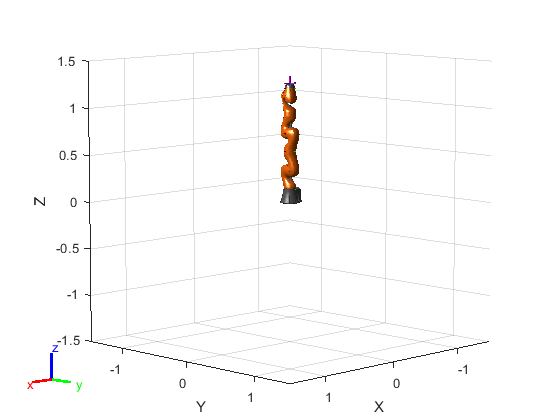

show(robot,initConfig);

For both the task space and the joint space case, we define an arbitrary starting pose `startConfig` and and arbitrary ending pose `endConfig. `

`startConfig` is defined arbitrarily as a position in which all joints are set to $\frac{\pi }{4}$ or 45 degrees. For `endConfig`, the position is first specified as an arbitrary homogeneous transform `endConfigH` that represents an end effector's final position and orientation

%%% Define Start Config %%%
startConfig = robot.homeConfiguration()

startConfig = 1×7 struct array with fields:
    JointName
    JointPosition


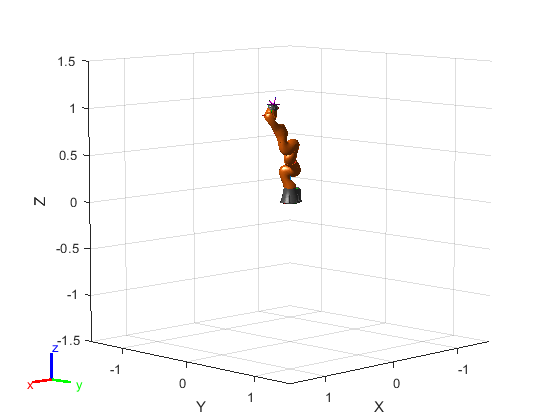

ans =   Axes (Primary) with properties:

             XLim: [-1.5000 1.5000]
             YLim: [-1.5000 1.5000]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.1300 0.1100 0.7750 0.8150]
            Units: 'normalized'

  Show all properties



%set all joints to pi/4
for i =1:size(startConfig,2)
    startConfig(i).JointPosition = pi/4;
end

%show start config
show(robot,startConfig)

startConfigH = getTransform(robot,startConfig,'iiwa_link_ee_kuka')

startConfigH =    -0.9937   -0.1098    0.0214    0.3855
    0.1098   -0.9205    0.3750    0.1473
   -0.0214    0.3750    0.9268    1.0810
         0         0         0    1.0000



% debug - show Jacobian of startConfig - not at singularity if rank = 6
% startJ = geometricJacobian(robot,startConfig,'iiwa_link_ee_kuka')
% rank(startJ) %6 is max

%%% Define Finish Config %%%
endConfigH = trvec2tform([.55, .35, .55])*axang2tform([0,0,1, -pi/4])

endConfigH =     0.7071    0.7071         0    0.5500
   -0.7071    0.7071         0    0.3500
         0         0    1.0000    0.5500
         0         0         0    1.0000


With the end effector position arbitrarily specified as x = 0.55m, y = 0.35m and z =0.55m with a rotation of $-\frac{\pi }{4}$ about the z-axis, we can determine the individual joint angles of $\theta_1$ through $\theta_7$ using the MATLAB `inverseKinematics()` solver. Here we specify all elements of the solution (3-axis positon and 3-axis orientation to all be equally and totally important to the solution by setting `weights = [1 1 1 1 1 1].  ` 

ik = inverseKinematics('RigidBodyTree',robot);
weights= [1 1 1 1 1 1];
endEffector = 'iiwa_link_ee_kuka'

endEffector = 'iiwa_link_ee_kuka'

guess = startConfig;

[endConfigSol,solInfo] = ik(endEffector,endConfigH,weights,guess)

endConfigSol = 1×7 struct array with fields:
    JointName
    JointPosition


solInfo = struct with fields:
           Iterations: 57
    NumRandomRestarts: 1
        PoseErrorNorm: 2.3098e-08
             ExitFlag: 1
               Status: 'success'


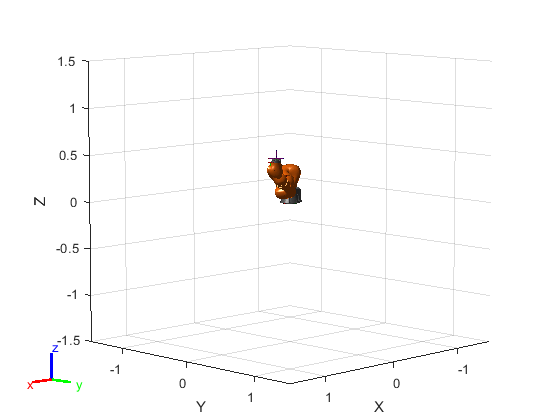

ans =   Axes (Primary) with properties:

             XLim: [-1.5000 1.5000]
             YLim: [-1.5000 1.5000]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.1300 0.1100 0.7750 0.8150]
            Units: 'normalized'

  Show all properties



show(robot,endConfigSol)

endConfigH_ik = getTransform(robot,endConfigSol,'iiwa_link_ee_kuka')

endConfigH_ik =     0.7071    0.7071   -0.0000    0.5500
   -0.7071    0.7071    0.0000    0.3500
    0.0000   -0.0000    1.0000    0.5500
         0         0         0    1.0000



%Debug - again make sure we don't land ON a singularity
%finishJ = geometricJacobian(robot,endConfigSol,'iiwa_link_ee_kuka')
%rank(finishJ) %6 is max

With `getTransform,` we see that the inverse kinematics solver has produced the same 4x4 homogeneous matrix as we initially defined, which verifies that the joint angles calculated for this final pose are correct. 

With the starting and final ("end") position of the end effector and the joints defined, we may now go about planning the trajectory of the robot's end effector. The two methodologies, *task space *and *joint space* are compared below. 

### Task-Space Trajectory Planning Approach

The first method explored is the task space method. We realize the task space approach by defining waypoints for the end effector that are interpolated in between the start and end points of a given trajectory path.  

To create the waypoints, we define a timestep and a constant tool speed. Based on MATLAB tutorials for trajectory planning, we use 0.1 seconds as the timestep and 0.1 m/s as the tool speed. 

We may calculate the Euclidian distance between the start and end points of the trajectory and calculate the trajectory time by dividing this distance by the tool speed specified. From this calculation, we may further define a linear space of times (`trajTimes`). 

%%% Task Space traj planning %%%
%waypoints from startconfig to endconfig

%Define timestep and toolSpeeed
timestep = 0.1 %seconds

timestep = 0.1000

toolSpeed = 0.1 %m/s

toolSpeed = 0.1000


distance = norm(tform2trvec(startConfigH)-tform2trvec(endConfigH))

distance = 0.5917

initTime = 0; %begin at t=0
finalTime = (distance/toolSpeed) - initTime; %d/v = t
trajTimes = initTime:timestep:finalTime;
timeInterval = [trajTimes(1); trajTimes(end)]

timeInterval =          0
    5.9000


Given all of these defined variables, we can obtain a series of "frame" waypoints (i.e. homogeneous 4x4 matricies that define the position and orientaiton of the end effector at different points in the trajectory) by using the function `transformtraj`, and passing it the start 

%get end effector waypoints
[taskWaypoints,taskVelocities,taskAccel] = transformtraj(startConfigH,endConfigH,timeInterval,trajTimes); 

%debug - plot the waypoints 
% array_point_x = zeros(size(taskWaypoints,3),1);
% array_point_y = zeros(size(taskWaypoints,3),1);
% array_point_z = zeros(size(taskWaypoints,3),1);
% 
% for i = 1:size(taskWaypoints,3)
%     point = taskWaypoints(1:3,4,i);
%     array_point_x(i) = point(1,1);
%     array_point_y(i) = point(2,1); 
%     array_point_z(i) = point(3,1);
% end

%plot end effector waypoints
% plot3(array_point_x,array_point_y,array_point_z, '-.o');

To actually calculate the trajectory via a task-space approach, we pass the task space waypoints, `taskWaypoints`, calculated above to the `inverseKinematics() `solver in a for loop, have the solver solve the individual joint positions for each pose defined by the 4x4 homogeneous matrix "waypoints", and collect those waypoint-by-waypoint solutions in a positions solutions matrix, `qs`. 

ik = inverseKinematics('RigidBodyTree',robot);
count  = length(trajTimes);
weights= [1 1 1 1 1 1];
guess = startConfig;
ndof = length(guess);
qs = zeros(count,ndof);

for i = 1:size(taskWaypoints,3)
    pose = taskWaypoints(:,:,i);
    q_Sol = ik(endEffector,pose,weights,guess);
    qs(i,:)=[q_Sol(1).JointPosition q_Sol(2).JointPosition q_Sol(3).JointPosition q_Sol(4).JointPosition...
        q_Sol(5).JointPosition,q_Sol(6).JointPosition,q_Sol(7).JointPosition];
    guess = q_Sol;
end

We may first visualize the individual joint positions over time calculated using the task-space planning method. 

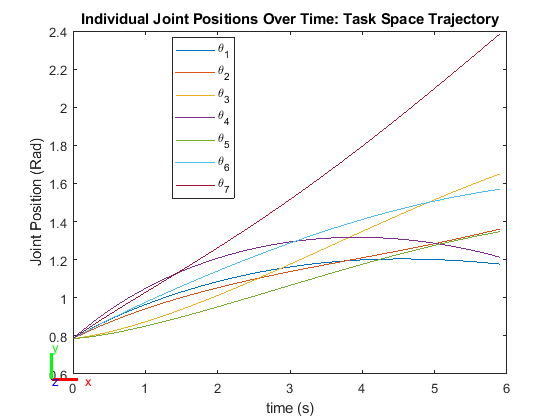

%plot individual joint positions over time for task space method
plot(trajTimes,qs(:,1),trajTimes, qs(:,2), ...
    trajTimes,qs(:,3),trajTimes,qs(:,4),trajTimes,qs(:,5),...
    trajTimes,qs(:,6),trajTimes, qs(:,7))
title("Individual Joint Positions Over Time: Task Space Trajectory")
legend('\theta_1','\theta_2','\theta_3','\theta_4',...
    '\theta_5','\theta_6','\theta_7','Location',"best")
ylabel('Joint Position (Rad)')
xlabel('time (s)')

Next, we can use solutions matrix `qs` to plot the task space trajectory of the end effector 

%to be safe, clear figure.
clf

%take transpose to get each row as joint position
qs_transpose = qs';

qs_transpose =     0.7854    0.8072    0.8279    0.8476    0.8664    0.8844    0.9016    0.9182    0.9341    0.9495    0.9643    0.9785    0.9922    1.0054    1.0182    1.0304    1.0422    1.0536    1.0645    1.0749    1.0849    1.0945    1.1037    1.1124    1.1207    1.1286    1.1360    1.1431    1.1497    1.1560    1.1618    1.1672    1.1723    1.1769    1.1812    1.1850    1.1885    1.1916    1.1944    1.1968    1.1988    1.2005    1.2018    1.2028    1.2034    1.2037    1.2037    1.2034    1.2028    1.2019
    0.7854    0.8040    0.8218    0.8388    0.8552    0.8710    0.8862    0.9009    0.9150    0.9286    0.9418    0.9546    0.9669    0.9788    0.9904    1.0015    1.0124    1.0229    1.0331    1.0430    1.0526    1.0620    1.0711    1.0800    1.0887    1.0972    1.1055    1.1136    1.1216    1.1294    1.1371    1.1447    1.1521    1.1595    1.1669    1.1741    1.1813    1.1885    1.1957    1.2028    1.2100    1.2172    1.2244    1.2316    1.2389    1.2463    1.2537    1.2612    

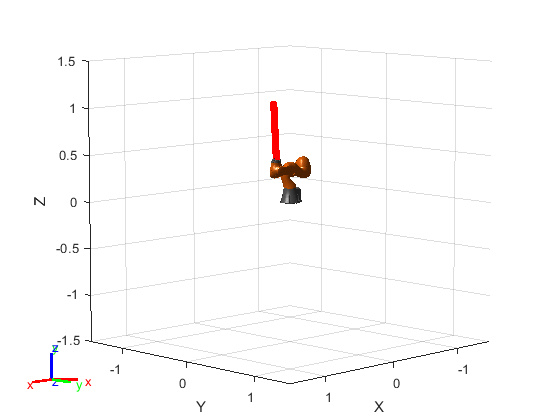


%need a starting pose
plotTaskSpaceConfig = startConfig;

%show initial pose of robot and hold on for animation
show(robot,startConfig,'PreservePlot',false,'Frames','off');
hold on

%loop to assign robot to poses, 
%draw animation of robot moving through trajectory. 
for i = 1:size(qs_transpose,2)
    %assign joint positions
    for j = 1:7
        plotTaskSpaceConfig(j).JointPosition = qs_transpose(j,i);
    end
    show(robot,plotTaskSpaceConfig);
    poseNow = getTransform(robot,plotTaskSpaceConfig,endEffector);
    %show robot in config specified in each iteration of outer loop
    show(robot,plotTaskSpaceConfig,'PreservePlot',false,'Frames','off');
    %superimpose plot of end effector on robot animation.
    plot3(poseNow(1,4),poseNow(2,4),poseNow(3,4),'r.','MarkerSize',20);
    drawnow;
end

The results of the task space trajectory simulation are shown with the trajectory in red. 

### Joint-Space Trajectory Planning Approach

The second method of trajectory planning explored is the joint space method. We realize the joint space approach by defining waypoints for each of the joints in the joint space (i.e. $\theta_1$ through $\theta_7$) from their starting positions to their ending positons. 

This approach requires only two inverse kinematics solutions - one for the starting position (which, because we defined our starting position in terms of joint positions, did not do) and one for the final position (which we have done already in the beginning). This is in contrast to the task space representations, which solves for the inverse kinematics of the manipulator at every end-effector waypoint to determine the pose of the manipulator and thus the joint positions. 

%%% Joint Space Traj Planning %%%

%To recap - here are our start and end joint positions from the beginning
startConfig

startConfig = 1×7 struct array with fields:
    JointName
    JointPosition


endConfigSol

endConfigSol = 1×7 struct array with fields:
    JointName
    JointPosition



%brute-force convert struct to double
for i=1:7
    jointInit(i) = startConfig(i).JointPosition;
    jointFinal(i) = endConfigSol(i).JointPosition;
end

%define waypoints for the individual joint angles
ctrlpoints = [jointInit', jointFinal'];
jointConfigArray = cubicpolytraj(ctrlpoints,timeInterval,trajTimes);

%NOTE: cubicpolytraj changes run to run. interesting!

Above, we define waypoints for the individual joint angles by first converting the start and end config structs into double arrays. We then package these arrays in 7x2 matrix `ctrlpoints` and pass these values to the function `cubicpolytraj` which creates a cubic-polynomial set of waypoints for each individual joint given their start and end positions and the time information for our trajectory. 

The plotting technique is essentially the same as the technique used in the task-space approach - using the individual joint angle waypoints determined by the cubic polynomial trajectory function, loop through each robot pose and plot each end effector position along with the robot in an animated way using `drawnow`.

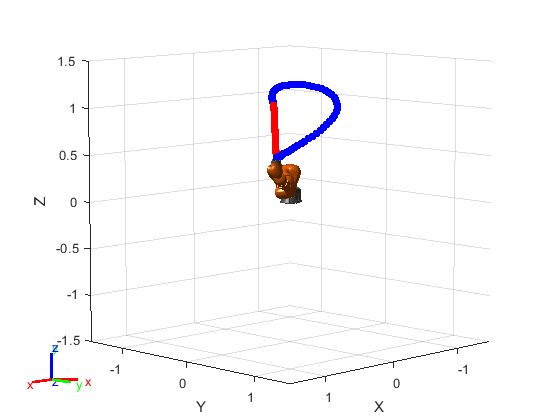

%show initial pose of robot and hold on for animation
show(robot,startConfig,'PreservePlot',false,'Frames','off');

%n.b. no clf used here!
%superimpose the joint space traj onto the task space traj
hold on

%need a starting config variable
plotTaskSpaceConfig = startConfig;

%loop to assign robot to poses, 
%draw animation of robot moving through trajectory.
for i = 1:size(jointConfigArray,2)
    for j = 1:7
        plotTaskSpaceConfig(j).JointPosition = jointConfigArray(j,i);
    end
    show(robot,plotTaskSpaceConfig);
    poseNow = getTransform(robot,plotTaskSpaceConfig,endEffector);
    %show robot in config specified in each iteration of outer loop
    show(robot,plotTaskSpaceConfig,'PreservePlot',false,'Frames','off');
    %superimpose plot of end effector on robot animation.
    plot3(poseNow(1,4),poseNow(2,4),poseNow(3,4),'b.','MarkerSize',20);
    drawnow;
end

The resulting plot is of the joint-space trajectory plotted on top of the existing task-space trajectory plot for comparison. 

Finally, we may visualize the individual joint waypoint positions over time for the joint-space planning method as specified using the `cubicpolytraj()` function.

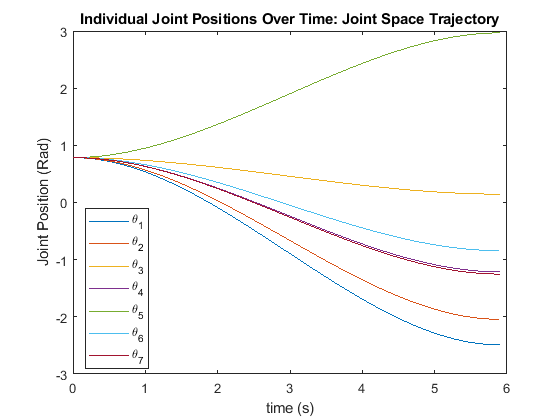

figure;
%plot individual joint positions over time for task space method
plot(trajTimes,jointConfigArray(1,:),trajTimes, jointConfigArray(2,:), ...
    trajTimes,jointConfigArray(3,:),trajTimes,jointConfigArray(4,:),trajTimes,jointConfigArray(5,:),...
    trajTimes,jointConfigArray(6,:),trajTimes, jointConfigArray(7,:))
title("Individual Joint Positions Over Time: Joint Space Trajectory")
legend('\theta_1','\theta_2','\theta_3','\theta_4',...
    '\theta_5','\theta_6','\theta_7','Location',"best")
ylabel('Joint Position (Rad)')
xlabel('time (s)')

## Discussion

The results successfully demonstrate the differences between the task-space and joint-space trajectory planning methods. Both methods employed successfully were able to move the end effector from the arbitrary start position to the arbitrary end positon. 

The tradeoffs of employing one solution over the other became apparent to the group after working through the assignment to realize both approaches. The task-space approach has the advantage of greater end-effector "precision" and predictablity in that the trajectory is a straight line from the start to end position. However, the disadvantage to this approach is the computational intensity needed to employ this method (i.e. the need to solve the inverse kinematics problem for each end effector waypoint). Conversely, the joint-space approach is a computationally simpler method in that the inverse kinematics problem only has to be solved for the start and end positions but has the disadvantage of producing a trajectory that is less direct (i.e. a curved line).  

We also visualized the differences in the individual joint motions. Comparing the joint-space trajectory to the task space trajectory in terms of individual joint movement, the joint-space trajectory appears smoother, more ordered and gradual as opposed to the task space trajectory, which appears to be less ordered and exhibits more variation between the joints in how they move. We can imagine that task-space planning may place greater demand on the joints and subject them to more varied and rapid movement, which may have physical implications for the manipulator. 

This was a challenging assignment, especially for the Joint Task trajectory. We finally figured that we had to transpose and get each row as desired joint position. From here, we utilized the KINOVA example and built off from as it was useful to understand what the assignment was asking for.

## References:

-  Spong, M. W. (2006). *Robot Modelling and Control Mark W. Spong* (926186803 726311037 M. W. Spong, Author). Hoboken, NJ: Wiley.

- [Kuka Programming reference](http://www.oir.caltech.edu/twiki_oir/pub/Palomar/ZTF/KUKARoboticArmMaterial/KUKA_SunriseOS_111_SI_en.pdf) 

- [Kuka LBR iiwa 7 R800 Spec Brochure](https://www.kuka.com/-/media/kuka-downloads/imported/9cb8e311bfd744b4b0eab25ca883f6d3/kuka_sensitiverobotics_lbriiwa_insert_en.pdf?rev=e035c0b1a17a402986cd9a7333cde7ee&hash=DDF40BC671FA663DCC0C314AAC7D7DFD)

- [Joint Space vs Task Space MATLAB Article](https://blogs.mathworks.com/racing-lounge/2019/11/06/robot-manipulator-trajectory/)

- [Kinova Gen3 Trajectory Planning MATLAB Example](https://www.mathworks.com/help/robotics/ug/plan-and-execute-trajectory-kinova-gen3.html;jsessionid=85bb859d989ea070f19819de7f0e)

- [Prof. Corke's Configuration and Task Space Lecture](https://robotacademy.net.au/lesson/task-and-configuration-space/https://robotacademy.net.au/lesson/task-and-configuration-space/)